# Tuning ottimale controllore PID - joint 1

## Schema di controllo

**Decentralizzato**

Un controllore indipendente per ogni giunto. Le mutue influenze tra giunti sono viste come disturbi causati da un sistema sull'altro da compensare nel controllore dell'altro

## Struttura di controllo (per il singolo giunto)

**Doppio loop posizione-velocità (cascata) + SP weight**

Ogni giunto è controllato da un controllore che riceve in input PV.POS e PV.VEL misurate e il set-point SP.POS. All'interno del controllore, alloggia il doppio loop, costituito, ad esempio, da:

- un *PD* per il **loop interno** (input: PV.VEL e MV del controllore esterno - output: coppia fornita al sistema)

- un *PID* per il **loop esterno** (input: PV.POS e SP.POS filtrato - output: velocità fornita in input al controllore interno)

- un *LPF* per implementare il **SP weight** (input: SP.POS - output SP.POS filtrato) 

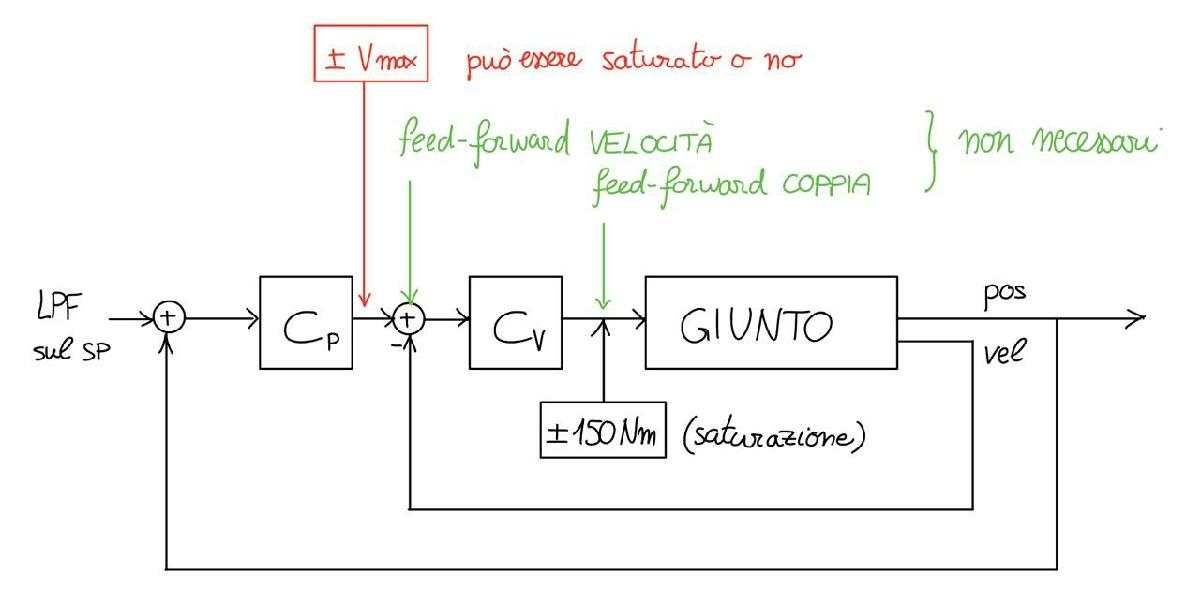

Note:

- implementare le **saturazioni** di coppia e velocità massima nei controllori opportuni

- implementare **anti-windup** per i controllori contenenti azione integrale

- valutare se possono servire i **feed-forward**

- loop interno veloce per la reiezione dei disturbi sul carico (influenze dell'altro giunto), loop esterno più lento ma sufficientemente veloce da seguire il SP in modo efficiente

- **taratura** di ogni sottocontrollore (`Cp_joint1`, `Cv_joint1`, `Cp_joint2`, `Cv_joint2`) in modo **ottimale** con `GlobalSearch`, includendo i **vincoli di robustezza e reiezione disturbi**

## Taratura ottima con vincoli robusti

Determinare $C(s)$ in modo che soddisfi vincoli in frequenza e ottimizzi una cifra di merito.

- PID con filtro sull'azione derivativa e filtro complessivo:    $C(s)=PID_{filt}(s)=\left(K_p+\frac{K_i}{s}+\frac{K_d\cdot s}{T_{fd}s+1}\right) \cdot \frac{1}{T_{fu}s+1}$

- PID con filtro sull'azione derivativa:    $C(s)=PID(s)=K_p+\frac{K_i}{s}+\frac{K_d\cdot s}{T_fs+1}$

- PD con filtro sull'azione derivativa:     $C(s)=PD(s)=K_p+\frac{K_d\cdot s}{T_fs+1}$

- PI:     $C(s)=PI(s)=K_p+\frac{K_i}{s}$

Eseguiamo il tuning nel dominio continuo (tariamo un controllore continuo sfruttando il modello continuo del processo) e in seguito discretizziamo il controllore ottenuto.

## Caricamento modelli dei processi

clear; clc;

Aggiungo opzione per evitare la molteplicità di 360° nella base

bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';

## Caricare il modello

simulation.author = 'CL_M';
Nprova = 2;

modelName = strcat(simulation.author,'_model_', num2str(Nprova));
directoryModel = strcat('.\estimated_models\data\',modelName);
load(directoryModel);

% Scelta dell'intervallo di frequenze 
w_inf = 0.1;
w_sup = 3000;

## Loop interno

**P interno con filtro su tutta l'azione di controllo**

Processo da controllare (da coppia motore a velocità)

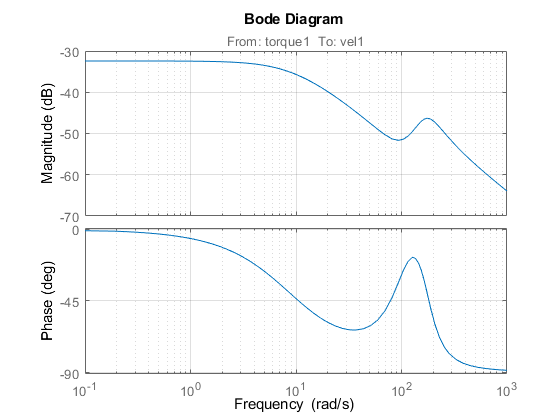

process = modelC_joint1;    % il modello deve essere nella forma dello spazio degli stati

bodeplot(process)
grid on;

### Cifra di merito da minimizzare


$$J=- \omega_{c}$$


- $\omega_c$: frequenza (pulsazione) di taglio

- $\omega_{c,des}$: valore desiderato

Le incognite del problema sono $x=[K_p, \; K_i, \; K_d, \; T_{fd}, \; T_{fu}]$ (alcune verranno forzate a 0, se non vogliamo utilizzarle).

internal_joint1.wc_des = 60;
J = @(x)pid_filt_cost_function(x,process,internal_joint1.wc_des);

### Vincoli

- massima sensitività $MS<1.4$ per garantire la robustezza (1.4 molto robusto, 2 poco robusto ma aggressivo)

- La funzione di anello chiuso $F$ deve avere modulo limitato con $\omega\geq\omega_h$

- La funzione fra disturbo sul carico e l'uscita deve modulo limitato quando $\omega\leq\omega_l$

- Il margine di fase deve essere almeno 60°

Parametri da tarare

% Massima sensitività
internal_joint1.MS = 2;

% Reiezione disturbo di misura
internal_joint1.wh = 2000;
internal_joint1.Fh_max = 0.1;

% Reiezione disturbo sul carico
internal_joint1.wl = 10;
internal_joint1.Dl_max = 0.1;

% Minimo margine di fase tollerabile
internal_joint1.PM_min = 60;

Per calcolare in maniera corretta $MS$ passo alla funzione anche il vettore delle pulsazioni naturali che voglio testare

w_vector=logspace(log10(w_inf),log10(w_sup))';
w_vector=sort(unique([w_vector;internal_joint1.wl;internal_joint1.wh]));

nlcon = @(x)pid_filt_constraints(x, process, w_vector, ...
                                 internal_joint1.MS, internal_joint1.wh, internal_joint1.Fh_max, ...
                                 internal_joint1.wl, internal_joint1.Dl_max, internal_joint1.PM_min);

### Ottimizzatore interno

Parametri da tarare

inner_optim = false;
if inner_optim

    timeout = 60*10; % secondi
    optimizer = "GlobalSearch";

    % [valore iniziale, limite inferiore, limite superiore]
    internal_joint1.aKp = [500, 100, 1000];
    internal_joint1.aKi = [0, 0, 0];
    internal_joint1.aKd = [0, 0, 0];
    internal_joint1.aTfd = [0, 0, 0];
    internal_joint1.aTfu = [1/70, 1/100, 1/40];
    
    % Lanciare ottimizzatore
    x = PID_param_optimization(internal_joint1.aKp,internal_joint1.aKi,internal_joint1.aKd,...
                               internal_joint1.aTfd,internal_joint1.aTfu,J,nlcon,timeout,optimizer)
    Kp=x(1); Ki=x(2); Kd=x(3); Tfd=x(4); Tfu=x(5); f_Tfu = 1/Tfu
    if Tfd ~=0
        fTfd = 1/Tfd
    end
end

### Controllore interno

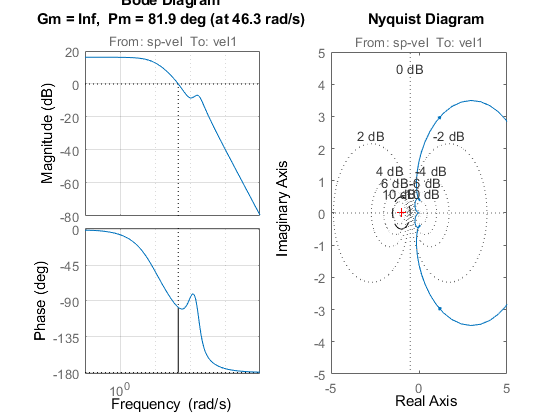

s = tf('s'); % variabile s per il dominio delle frequenze

manual_overwriting_int = true;
use_saved_inner = false;
if manual_overwriting_int
    Kp = 270;
    Ki = 0;
    Kd = 0;
    Tfd = 0;
    Tfu = 1/63;
elseif use_saved_inner
    load('.\src\controllers\params\PID_int_joint1.mat')
    Kp = PID_int_joint1.Kp;
    Ki = PID_int_joint1.Ki;
    Kd = PID_int_joint1.Kd;
    Tfd = PID_int_joint1.Tfd;
    Tfu = PID_int_joint1.Tfu;
end

% progettiamo un controllore nella forma della funzione di trasferimento
Cv_joint1 = (Kp+Ki/s+Kd*s/(Tfd*s+1)) * 1/(Tfu*s+1);
Cv_joint1.InputName = 'sp-vel';
Cv_joint1.OutputName = 'torque';

Loop_int_joint1 = process*Cv_joint1; % funzione di anello aperto interna


figure
subplot(1,2,1)
margin(Loop_int_joint1)
grid on; hold on
hold off

subplot(1,2,2)
nyquist(Loop_int_joint1)
axis equal; grid on; hold on;
angolo=linspace(-pi,pi);
plot(-1+1/internal_joint1.MS*sin(angolo),1/internal_joint1.MS*cos(angolo),'--k')
hold off
xlim([-5 5]); ylim([-5 5])

Salvataggio parametri tarati

PID_int_joint1.Kp = Kp;
PID_int_joint1.Ki = Ki;
PID_int_joint1.Kd = Kd;
PID_int_joint1.Tfd = Tfd;
PID_int_joint1.Tfu = Tfu;
paramsDirectory = '.\src\controllers\params\PID_int_joint1';    
save(paramsDirectory,'PID_int_joint1')

## Loop esterno

**PID esterno con filtro su tutta l'azione di controllo**

Processo da controllare (da velocità - set point per il controllore interno - a posizione)

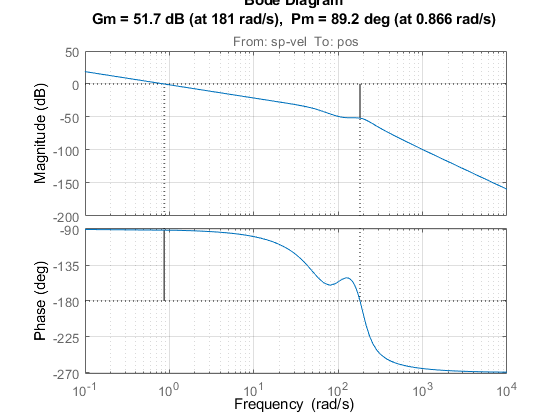

process_ext = minreal(tf(Cv_joint1*modelC_joint1 * 1/(1+Cv_joint1*modelC_joint1)) * 1/s);
process_ext.InputName = 'sp-vel';
process_ext.OutputName = 'pos';

figure
margin(process_ext)
grid on;

Necessario integratore perchè il modello in uscita fornisce la velocità, mentre noi vogliamo controllare la posizione.

**N.B.: il controllore esterno ****non**** vede **`Cv*P*1/s`**, ma **`Cv*P/(1+Cv*P)*1/s`** (in pratica vede tutto il sistema interno in closed-loop + l'integratore)**

### Cifra di merito da minimizzare

external_joint1.wc_des = 50;
J = @(x)pid_filt_cost_function(x,process_ext,external_joint1.wc_des);

### Vincoli

Parametri da tarare

% Massima sensitività
external_joint2.MS = 1.6;

% Reiezione disturbo di misura
external_joint2.wh = 2000;
external_joint2.Fh_max = 0.1;

% Reiezione disturbo sul carico
external_joint2.wl = 1;
external_joint2.Dl_max = 0.1;

% Minimo margine di fase tollerabile
external_joint2.PM_min = 65;

Per calcolare in maniera corretta $MS$ passo alla funzione anche il vettore delle pulsazioni naturali che voglio testare

w_vector=logspace(log10(w_inf),log10(w_sup))';
w_vector=sort([w_vector;external_joint2.wl;external_joint2.wh]);

nlcon = @(x)pid_filt_constraints(x, process_ext, w_vector, ...
                                 external_joint2.MS, external_joint2.wh, external_joint2.Fh_max, ...
                                 external_joint2.wl, external_joint2.Dl_max, external_joint2.PM_min);

### Ottimizzatore esterno

Parametri da tarare

ext_optim = false;

if ext_optim

    timeout = 60*10; % secondi
    optimizer = "GlobalSearch";

    % [valore iniziale, limite inferiore, limite superiore]
    external_joint1.aKp = [100, 1, 1000];
    external_joint1.aKi = [0.01, 0.001, 1];
    external_joint1.aKd = [0, 0, 0];
    external_joint1.aTfd = [0, 0, 0];
    external_joint1.aTfu = [0, 0, 0];
    
    % Lanciare ottimizzatore
    x = PID_param_optimization(external_joint1.aKp,external_joint1.aKi,external_joint1.aKd, ...
                               external_joint1.aTfd,external_joint1.aTfu,J,nlcon,timeout,optimizer)
    Kp=x(1); Ki=x(2); Kd=x(3); Tfd=x(4); Tfu=x(5);
end

### Controllore esterno

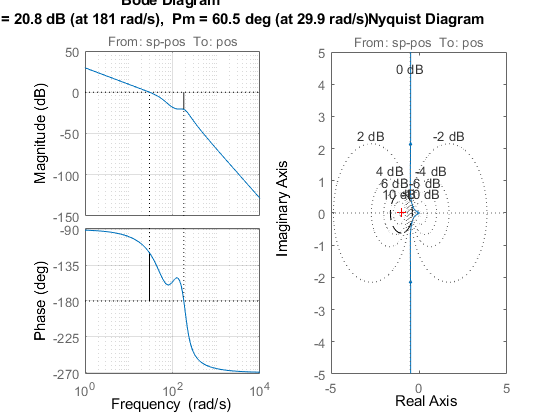

manual_overwriting_ext = true;
use_saved_ext = false;

if manual_overwriting_ext
    Kp = 35;
    Ki = 0.01;
    Kd = 0;
    Tfd = 0;
    Tfu = 0;
elseif use_saved_ext
    load('.\src\controllers\params\PID_ext_joint1.mat')
    Kp = PID_ext_joint1.Kp;
    Ki = PID_ext_joint1.Ki;
    Kd = PID_ext_joint1.Kd;
    Tfd = PID_ext_joint1.Tfd;
    Tfu = PID_ext_joint1.Tfu;
end

% inserire filtro per introdurre polo ad alta frequenza (rendere il sistema proprio)
% Tfu = 1/1000;

% progettiamo un controllore nella forma della funzione di trasferimento
Cp_joint1 = (Kp+Ki/s+Kd*s/(Tfd*s+1)) * 1/(Tfu*s+1);
Cp_joint1.InputName = 'sp-pos';
Cp_joint1.OutputName = 'sp-vel';

Loop_ext_joint1 = process_ext*Cp_joint1;

figure
subplot(1,2,1)
margin(Loop_ext_joint1)
grid on; hold on
hold off

subplot(1,2,2)
nyquist(Loop_ext_joint1)
axis equal; grid on; hold on;
angolo=linspace(-pi,pi);
plot(-1+1/external_joint2.MS*sin(angolo),1/external_joint2.MS*cos(angolo),'--k')
hold off
xlim([-5 5]); ylim([-5 5])

Salvataggio parametri tarati

PID_ext_joint1.Kp = Kp;
PID_ext_joint1.Ki = Ki;
PID_ext_joint1.Kd = Kd;
PID_ext_joint1.Tfd = Tfd;
PID_ext_joint1.Tfu = Tfu;
    
paramsDirectory = '.\src\controllers\params\PID_ext_joint1';    
save(paramsDirectory,'PID_ext_joint1') 

## Discretizzazione

st = 1e-3; % tempo di campionamento

### Loop interno

PID_int_joint1.st = st;

% Discretizzazione della fdt
[PID_int_joint1.coeff_num_D, PID_int_joint1.coeff_den_D] = discretizzazionePID_fn(PID_int_joint1.Kp,PID_int_joint1.Ki,PID_int_joint1.Kd,...
                                                            PID_int_joint1.Tfd,PID_int_joint1.Tfu,PID_int_joint1.st);
% Taratura antiwindup
PID_int_joint1.Kaw=0;
PID_int_joint1.Kaw_ext=0;

% Costruzione controllore
PID_int_joint1.controller = PID_filt_Controller(PID_int_joint1.st,PID_int_joint1.Ki,...
                                     PID_int_joint1.coeff_num_D,PID_int_joint1.coeff_den_D,...
                                     PID_int_joint1.Kaw, PID_int_joint1.Kaw_ext);

### Loop Esterno

PID_ext_joint1.st = st;

% Discretizzazione della fdt
[PID_ext_joint1.coeff_num_D, PID_ext_joint1.coeff_den_D] = discretizzazionePID_fn(PID_ext_joint1.Kp,PID_ext_joint1.Ki,PID_ext_joint1.Kd,...
                                                            PID_ext_joint1.Tfd,PID_ext_joint1.Tfu,PID_ext_joint1.st);
% Taratura antiwindup
PID_ext_joint1.Kaw=0;

if PID_ext_joint1.Ki ~= 0
    PID_ext_joint1.Kaw_ext = PID_ext_joint1.Ki;
else
    PID_ext_joint1.Kaw_ext = 0;
end

% Costruzione controllore
PID_ext_joint1.controller = PID_filt_Controller(PID_ext_joint1.st,PID_ext_joint1.Ki,...
                                     PID_ext_joint1.coeff_num_D,PID_ext_joint1.coeff_den_D,...
                                     PID_ext_joint1.Kaw, PID_int_joint1.Kaw_ext);

Salvataggio dati discreti

paramsDirectory = '.\src\controllers\params\PID_int_joint1';
save(paramsDirectory,'PID_int_joint1')
paramsDirectory = '.\src\controllers\params\PID_ext_joint1';
save(paramsDirectory,'PID_ext_joint1') 